`3. ``对模拟周期信号进行频谱分析`

`选择样频率``Fs=64Hz``，对变换区间`N=16`，`32`，`64`三种情况进行谱分析。分别打印其幅频特性曲线，并进行对比、分析、讨论。`

`这里利用实验一中所 定义的采样函数`

`xa(t) 的 最高频率为 10Hz, 因此Fs=64Hz进行采样不会导致混叠`

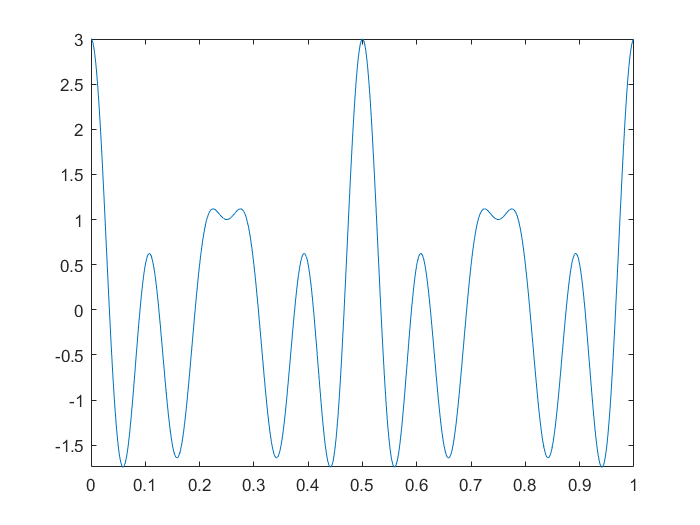

%=======定义x6(t) =======
x6t = @(t) cos(8*pi*t) + cos(16*pi*t) + cos(20 * pi *t);
N1 = 16; N2 = 32; N3 = 64;  % N的三种情况
fplot(x6t , [0, 1])  % 两个周期


%=======对x6(t)进行一个周期的等间隔采样 =======
x6n = sample_fun(x6t,1/2*Fs,64 );

下面进行谱分析

由于, 因此

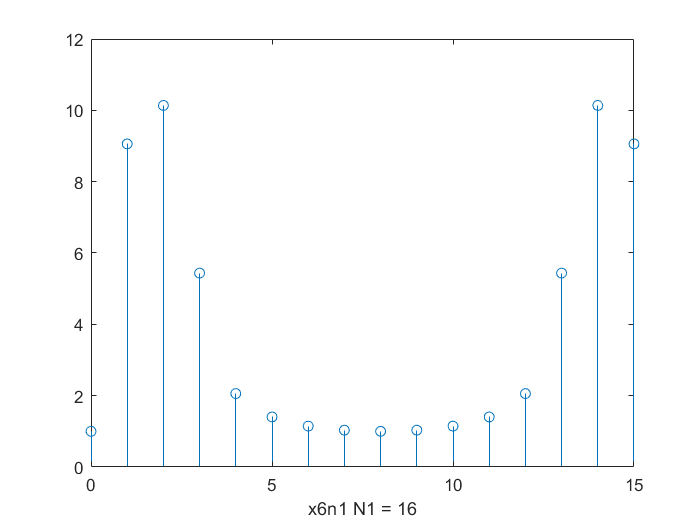

%=======x6n1 N1 = 16 =======
y6n1 =  fft(x6n, N1) ; % x1n N1 = 8
stem(0:length(y6n1) - 1, abs(y6n1))
xlabel("x6n1 N1 = 16");

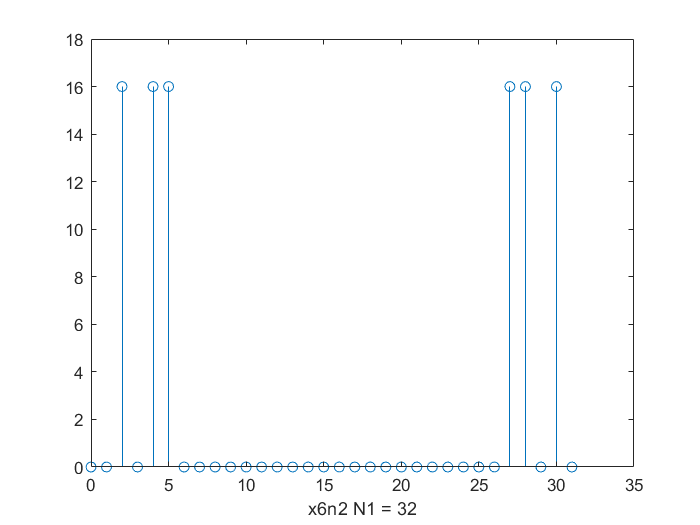


%=======x6n2 N1 = 32 =======
y6n2 =  fft(x6n, N2) ; % x1n N1 = 8
stem(0:length(y6n2) - 1, abs(y6n2))
xlabel("x6n2 N1 = 32");

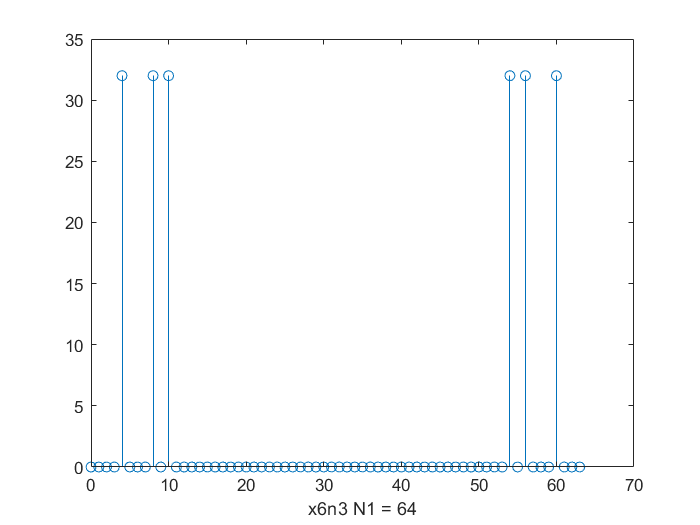


%=======x6n3 N1 = 64 =======
y6n3 =  fft(x6n, N3) ; % x1n N1 = 8
stem(0:length(y6n3) - 1, abs(y6n3))
xlabel("x6n3 N1 = 64");